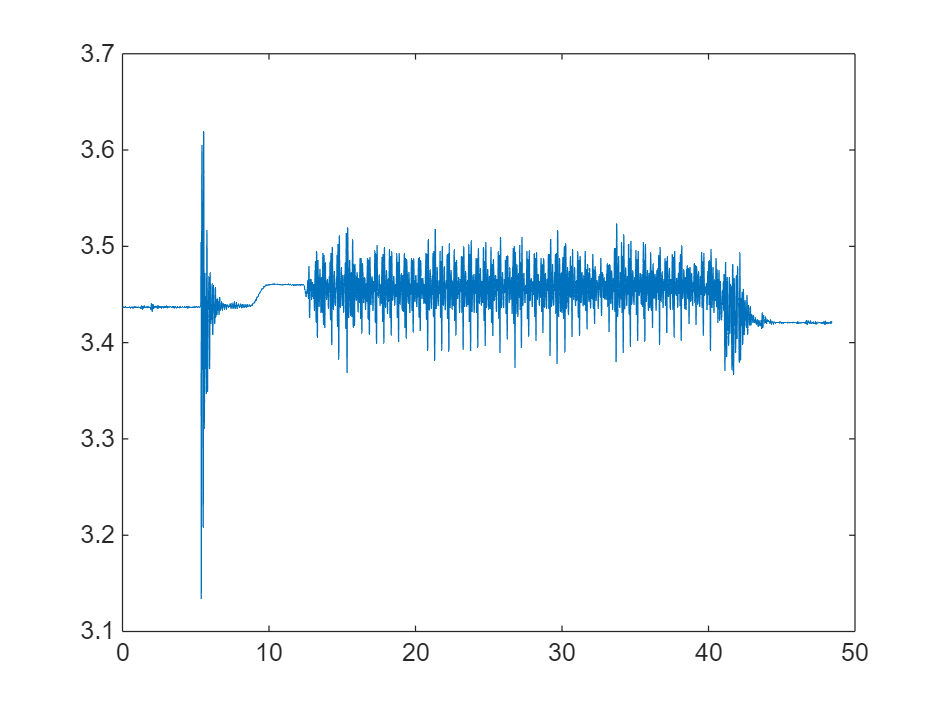

acc_file = 'acc_1mm_4V_lg.txt';
%% read acc data
% Open the file for reading
fid = fopen(acc_file, 'r');
if fid == -1
    error('File cannot be opened.');
end

% Initialize arrays for valid data
timeSecs = [];
value1  = [];
value2  = [];

% Define a regular expression pattern.
% This pattern looks for:
%  - One or more digits for hours, minutes, seconds, and milliseconds.
%  - The literal " -> " between the time and the two numeric values.
%  - Two floating-point numbers separated by a comma.
pattern = '^(\d+):(\d+):(\d+):(\d+)\s*->\s*(-?\d+\.\d+),(-?\d+\.\d+)$';

while ~feof(fid)
    tline = fgetl(fid);

    % Use regexp to see if the line matches the complete pattern.
    tokens = regexp(tline, pattern, 'tokens');

    if ~isempty(tokens)
        % Convert token strings to numbers.
        nums = cellfun(@str2double, tokens{1});
        h  = nums(1);
        m  = nums(2);
        s  = nums(3);
        ms = nums(4);
        v1 = nums(5);
        v2 = nums(6);

        % Convert the time into seconds.
        timeInSec = h*3600 + m*60 + s + ms/1000;

        % Append to our arrays
        timeSecs(end+1, 1) = timeInSec;
        value1(end+1, 1)  = v1;
        value2(end+1, 1)  = v2;
    end
    % If tokens is empty, the line is incomplete or doesn’t match the format.
    % In that case, it is automatically disregarded.
end

% Close the file
fclose(fid);

% Display the results (as a table for clarity)
acc_time = timeSecs;
time_diff = acc_time(2:end) - acc_time(1:end-1);

ts = mean(time_diff);
std_ts = std(time_diff);
fs = 1/ts;

weeks = 34;

acc_file = strcat('acc_',num2str(weeks),'wk_sync.txt');
fid = fopen(acc_file, 'r');
if fid == -1
    error('File cannot be opened.');
end

% Initialize arrays for valid data
timeSecs = [];
value1  = [];
value2  = [];

% Define a regular expression pattern.
% This pattern looks for:
%  - One or more digits for hours, minutes, seconds, and milliseconds.
%  - The literal " -> " between the time and the two numeric values.
%  - Two floating-point numbers separated by a comma.
pattern = '^(-?\d+\.\d+),(-?\d+\.\d+)$';

while ~feof(fid)
    tline = fgetl(fid);

    % Use regexp to see if the line matches the complete pattern.
    tokens = regexp(tline, pattern, 'tokens');

    if ~isempty(tokens)
        % Convert token strings to numbers.
        nums = cellfun(@str2double, tokens{1});
        v1 = nums(1);
        v2 = nums(2)./100;

        % Convert the time into seconds.

        % Append to our arrays
        value1(end+1, 1)  = v1;
        value2(end+1, 1)  = v2;
    end
    % If tokens is empty, the line is incomplete or doesn’t match the format.
    % In that case, it is automatically disregarded.
end

% Close the file
fclose(fid);
acc_data = [value1,value2];

time = 0:ts:2000;
time = time(1:length(value2));

figure;
plot(time,value2)

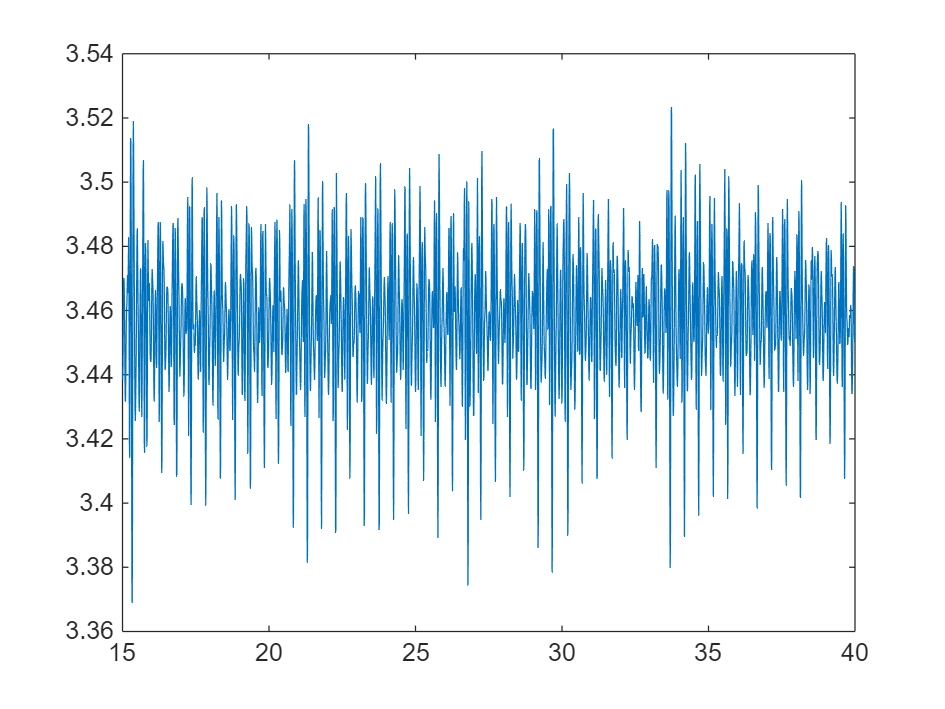


cut_ind = find(time>15&time<40);
cut_time = time(cut_ind);
cut_data = value2(cut_ind);

figure;
plot(cut_time,cut_data);

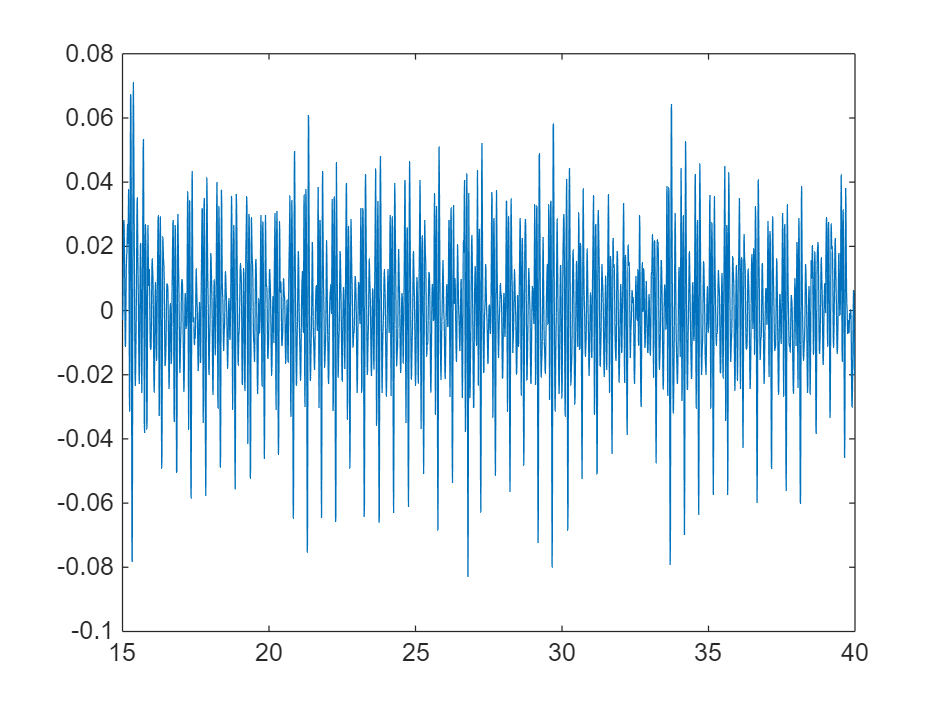


% High pass to try to remove baseline

cutoff_freq = 0.3;    % Cutoff frequency in Hz
filter_order = 4;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
hp_data= filtfilt(b, a, cut_data);

figure;
plot(cut_time,hp_data)

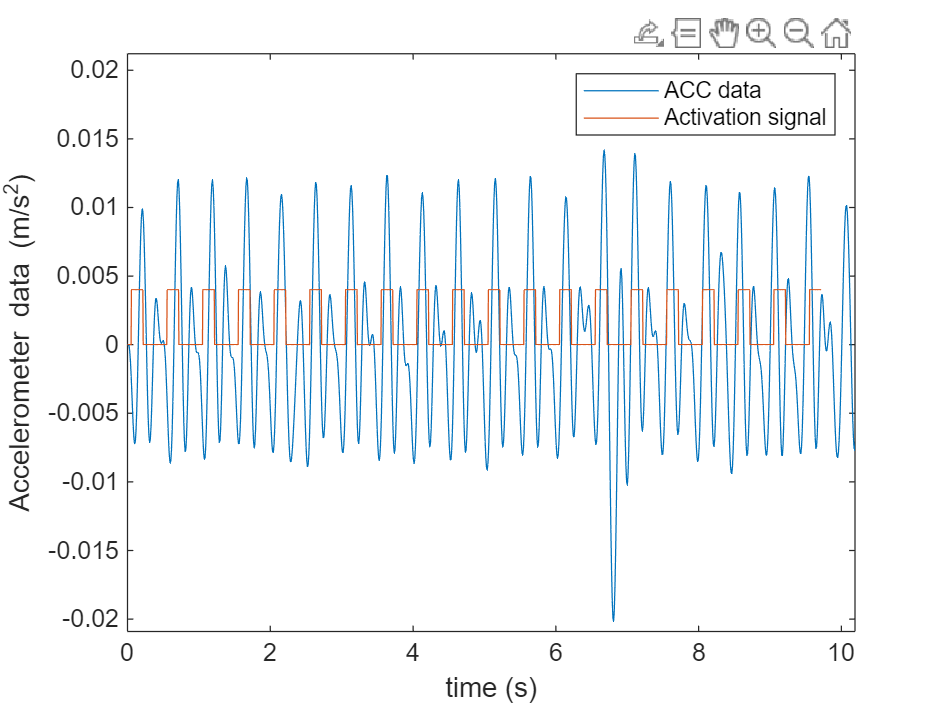

% Low pass to try to remove noise

cutoff_freq = 6;    % Cutoff frequency in Hz
filter_order = 5;    % Filter order (adjust as needed)

% lpf = designfilt('lowpassiir', ...
%     'FilterOrder', filter_order, ...
%     'HalfPowerFrequency', cutoff_freq, ...
%     'SampleRate', fs, ...
%     'DesignMethod', 'butter');

[b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');
bp_data= filtfilt(b, a, hp_data);

act_time = 20:0.005:30;
act_time(end) = [];
act_time = act_time-0.28;
single_act_data = [zeros(1,67),ones(1,33)]*0.004;
act_data = repmat(single_act_data,1,20);

figure;
plot(cut_time-20,bp_data)
hold on
plot(act_time-20,act_data)
hold off
xlim([0 10.19])
ylim([-0.0209 0.0212])
legend('ACC data','Activation signal')
xlabel('time (s)')
ylabel('Accelerometer data (m/s^2)')

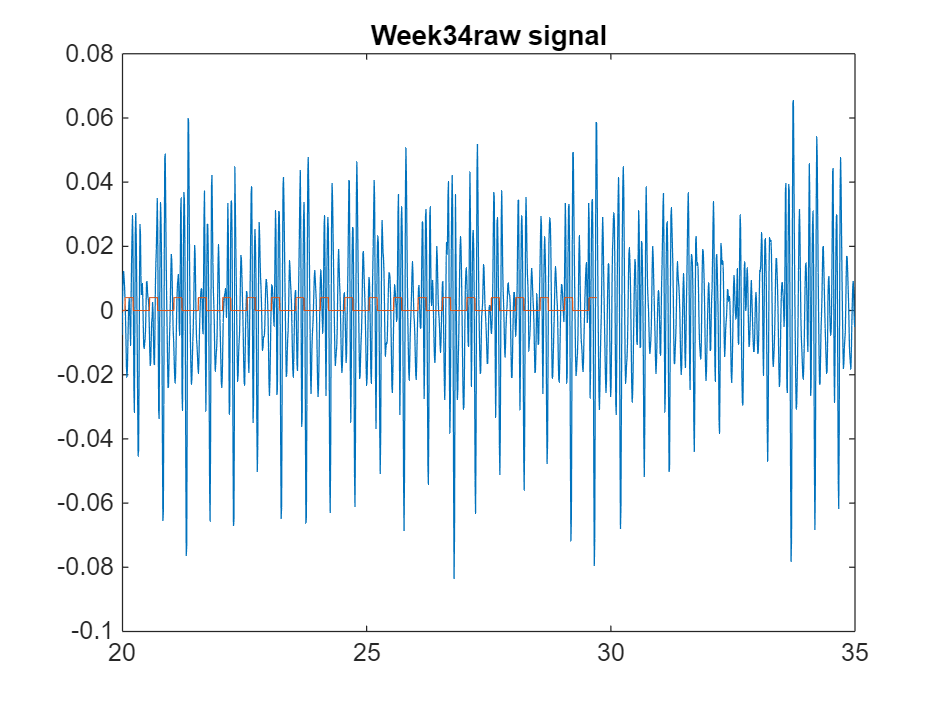





figure;
plot(cut_time,cut_data-mean(cut_data))
hold on
plot(act_time,act_data)
hold off
xlim([20 35])
title_txt = strcat('Week ',num2str(weeks),'raw signal');
title(title_txt)


clip_data = bp_data(cut_time>20&cut_time<30);
clip_time = cut_time(cut_time>20&cut_time<30);


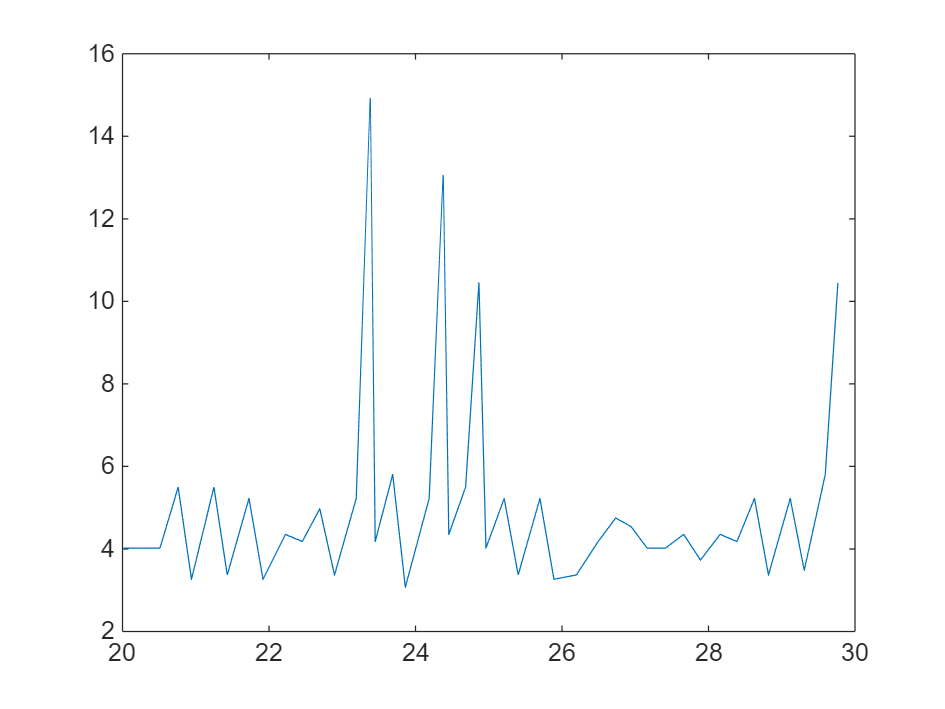

% Frequency calculation
cross_idx = find(clip_data(1:end-1).*clip_data(2:end) < 0 );
time_cross = clip_time(cross_idx);
data_cross = clip_data(cross_idx);
pos_cross_idx = find(data_cross > 0);
pos_time_cross = time_cross(pos_cross_idx);
cross_time_diff = pos_time_cross(2:end) - pos_time_cross(1:end-1);
cross_freq = 1./ cross_time_diff;
figure;
plot(pos_time_cross(1:end-1),cross_freq)

% magnitude
RMS = sqrt(mean(clip_data.^2))

RMS = 0.0060


% p2p
[pk_vals, pk_locs] = findpeaks(clip_data, clip_time,'MinPeakHeight', 0.005);
[tr_vals_neg, tr_locs] = findpeaks(-clip_data, clip_time,'MinPeakHeight', 0.005);
tr_vals = -tr_vals_neg;

if tr_locs(1) < pk_locs(1)
    tr_locs(1) = []; tr_vals(1) = [];
end

N = min(numel(pk_locs), numel(tr_locs));
pk_locs = pk_locs(1:N);
pk_vals = pk_vals(1:N);
tr_locs = tr_locs(1:N);
tr_vals = tr_vals(1:N);

p2p = pk_vals - tr_vals;
mean_p2p = mean(p2p)

mean_p2p = 0.0190

std_p2p = std(p2p)

std_p2p = 0.0020